## Exercice final optimisation globale 

El Imami Imane

Jacquot Vincent 

## Partie 1 : optimisation mono-objectif

### Définition des input

clear
data = load('EteV35Nu10.txt');
heure  = data(:,1)';
D = data(:,2)';
Peol = data(:,3)';
Ppv = data(:,4)';
Prix = data(:,5);
QH2_min = 100;
N = length(heure);
Celec = 1;
Pelec_min = 5;
Pelec_max = 30;
relec = 0.6;

fobj = @(elec) (elec(1,1:N) + D - Ppv - Peol)*Prix + Celec*sum(elec(1,1:N));  
lb = zeros(1,2*N);
ub = [Pelec_max*ones(1,N) , ones(1,N)];
A = [eye(N) , -Pelec_max*eye(N)
     -eye(N) , Pelec_min*eye(N)
     -ones(1,N)*relec , zeros(1,N)];
b = [zeros(2*N,1) ; -QH2_min];
Aeq = [];
beq = [];
nonlcon = [];


### Solveur Genetic Algorithm

Intcon = (N+1):2*N;
pop = 200;
options = optimoptions('ga');
options.PopulationSize = pop;
On = randi(2,pop,N) - 1;
P = (Pelec_min + rand(pop,N)*(Pelec_max - Pelec_min)).*On;
Init = [P , On];
options.InitialPopulationMatrix = Init;
[x,fval,exitflag,output,population,scores] = ga(fobj,2*N,A,b,Aeq,beq,lb,ub,nonlcon,Intcon,options);

Optimization terminated: average change in the penalty fitness value less than options.FunctionTolerance
but constraints are not satisfied.


disp('Coût en euros : ')

Coût en euros : 


disp(fval)

   2.4400e+03



disp('Quantité d hydrogène produite :')

Quantité d hydrogène produite :


disp(sum(x(1,1:N))*relec)

  214.6756



### Solveur Global Search

x0 = zeros(1,2*N);
x0(1,N+1:2*N) = randi(2,1,N) - 1;
x0(1,1:N)= (Pelec_min + rand(1,N)*(Pelec_max - Pelec_min)).*x0(1,N+1:2*N);
probleme = createOptimProblem('fmincon','x0',x0,'objective',fobj,'lb',lb,'ub',ub,'Aineq',A,'bineq',b);
[x,fval,exitflag,output,solutions] = run(GlobalSearch,probleme);

GlobalSearch stopped because it analyzed all the trial points.

All 52 local solver runs converged with a positive local solver exit flag.


disp('Coût en euros : ')

Coût en euros : 


disp(fval)

  378.6189



disp('Quantité d hydrogène produite :')

Quantité d hydrogène produite :


disp(sum(x(1,1:N))*relec)

  100.0000



Les résultats de Global Search sont meilleurs que ceux de Genetic Algorithm qui est très dépendant de l'initialisation. Un On aura tendance à conserver sa valeur initiale avec ga. L'optimum global n'est donc pas atteint, le solveur reste bloqué dans un optimum local. Gs rend une valeur qui semble optimale et la majorité des On sont proches de 0 ou 1 avec des 1 quand l'électricité est la moins chère.

### Etude paramétrique sur la valeur de QH2

QH2_min_k = linspace(0,200,10);
bk = b;
x0 = zeros(1,2*N);
x0(1,N+1:2*N) = randi(2,1,N) - 1;
x0(1,1:N)= (Pelec_min + rand(1,N)*(Pelec_max - Pelec_min)).*x0(1,N+1:2*N);
couts = zeros(1,10);
for k = 1:10
    bk(2*N+1) = - QH2_min_k(k);
    probleme = createOptimProblem('fmincon','x0',x0,'objective',fobj,'lb',lb,'ub',ub,'Aineq',A,'bineq',bk);
    [x,fval,exitflag,output,solutions]=run(GlobalSearch,probleme);
    couts(k) = fval;
    
end

GlobalSearch stopped because it analyzed all the trial points.

All 2 local solver runs converged with a positive local solver exit flag.

GlobalSearch stopped because it analyzed all the trial points.

42 out of 44 local solver runs converged with a positive local solver exit flag.

GlobalSearch stopped because it analyzed all the trial points.

36 out of 45 local solver runs converged with a positive local solver exit flag.

GlobalSearch stopped because it analyzed all the trial points.

All 29 local solver runs converged with a positive local solver exit flag.

GlobalSearch stopped because it analyzed all the trial points.

All 62 local solver runs converged with a positive local solver exit flag.

GlobalSearch stopped because it analyzed all the trial points.

62 out of 63 local solver runs converged with a positive local solver exit flag.

GlobalSearch stopped because it analyzed all the trial points.

All 63 local solver runs converged with a positive local solver exit flag.

Glo

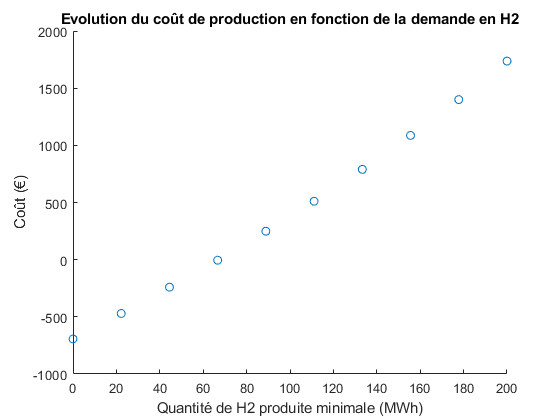

figure
scatter(QH2_min_k,couts)
xlabel('Quantité de H2 produite minimale (MWh)')
ylabel('Coût (€)')
title('Evolution du coût de production en fonction de la demande en H2')

### Influence de BasinRadiusFactor sur Global Search

x0 = zeros(1,2*N);
x0(1,N+1:2*N) = randi(2,1,N) - 1;
x0(1,1:N)= (Pelec_min + rand(1,N)*(Pelec_max - Pelec_min)).*x0(1,N+1:2*N);
probleme = createOptimProblem('fmincon','x0',x0,'objective',fobj,'lb',lb,'ub',ub,'Aineq',A,'bineq',b);
gs = GlobalSearch;
rad = linspace(0.1,0.5,5);
sol = zeros(3,5);
for k = 1:5
    gs.BasinRadiusFactor = rad(k);
    tic
    [x,fval,exitflag,output,solutions]=run(gs,probleme);
    t = toc;
    sol(:,k) = [fval ; t ; output.funcCount];
end

GlobalSearch stopped because it analyzed all the trial points.

36 out of 60 local solver runs converged with a positive local solver exit flag.

GlobalSearch stopped because it analyzed all the trial points.

All 60 local solver runs converged with a positive local solver exit flag.

GlobalSearch stopped because it analyzed all the trial points.

All 57 local solver runs converged with a positive local solver exit flag.

GlobalSearch stopped because it analyzed all the trial points.

34 out of 67 local solver runs converged with a positive local solver exit flag.

GlobalSearch stopped because it analyzed all the trial points.

All 59 local solver runs converged with a positive local solver exit flag.


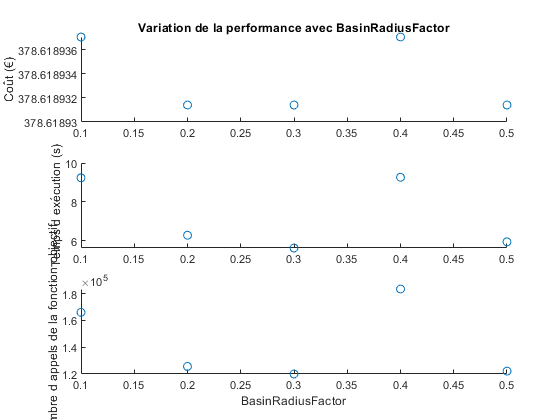

figure
subplot(3,1,1)
scatter(rad,sol(1,:))
title('Variation de la performance avec BasinRadiusFactor')
ylabel('Coût (€)')
subplot(3,1,2)
scatter(rad,sol(2,:))
ylabel('Temps d exécution (s)')
subplot(3,1,3)
scatter(rad,sol(3,:))
ylabel('Nombre d appels de la fonction objectif')
xlabel('BasinRadiusFactor')

Le résultat n'est pas impacté par la valeur du paramètre BasinRadiusFactor, par contre pour une valeur de 0.1, le nombre d'appels de la fonction objectif et le temps d'exécution sont plus faibles. 

## Partie 2 : optimisation multi-objectif  

### Définition des input

clear
data = load('AutonV50Nu40.txt');
heure  = data(:,1)';
D = data(:,2)';
Peol = data(:,3)';
Ppv = data(:,4)';
Prix = data(:,5);
QH2_max = 20;
QH2_prod_max = 20; % ajout d'une prod max pour restreindre le domaine du front de Pareto
N = length(heure);
Cpac = -4;
Celec = 1;
Ppac_max = 15;
Pelec_max = 30;
rpac = 0.8;
relec = 0.6;
% Nous avons modifié la fonction objectif pour valoriser la production de H2 
fobj = @(P) [ sum(P(1,N+1:2*N))/rpac - sum(P(1,1:N))*relec , (P(1,1:N) + D - Ppv - Peol - P(1,N+1:2*N))*Prix + Celec*sum(P(1,1:N)) + Cpac*sum(P(1,N+1:2*N))];
lb = zeros(1,2*N);
ub = [Pelec_max*ones(1,N) , Ppac_max*ones(1,N)];
A = [-ones(1,N)*relec , ones(1,N)/rpac % La contrainte aussi est modifiée, 
     ones(1,N)*relec , zeros(1,N)];    % on regarde l'évolution du stock de H2 et non la quantité consommée
b = [QH2_max ; QH2_prod_max];
Aeq = [];
beq = [];
nonlcon = [];
n_points = 10;
n_pop = 200;

### Solveur 'gamultiobj'

options = optimoptions('gamultiobj');
options.PopulationSize = n_pop;
options.ParetoFraction = n_points/n_pop;
On = randi(2,n_pop,N) - 1; % Initialisation qui respecte les contraintes
Init = [On.*rand(n_pop,N)*QH2_prod_max/relec/24 , (1 - On).*rand(n_pop,N)*QH2_max*rpac/24];
options.InitialPopulationMatrix = Init;
[x_ga,fval_ga,exitflag_ga,output_ga,population_ga,scores_ga] = gamultiobj(fobj,2*N,A,b,Aeq,beq,lb,ub,nonlcon,options);

Optimization terminated: average change in the spread of Pareto solutions less than options.FunctionTolerance.


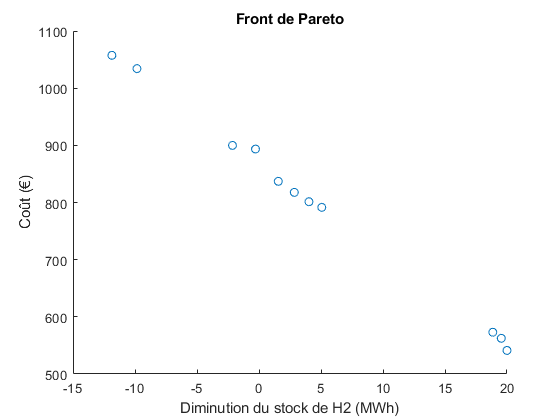

figure
scatter(fval_ga(:,1),fval_ga(:,2))
xlabel('Diminution du stock de H2 (MWh)')
ylabel('Coût (€)')
title('Front de Pareto')

### Solveur 'paretosearch'

options = optimoptions('paretosearch');
options.ParetoSetSize = n_points;
options.MinPollFraction = 1;
On = randi(2,n_points,N) - 1;
Init = [On.*rand(n_points,N)*QH2_prod_max/relec/24 , (1 - On).*rand(n_points,N)*QH2_max*rpac/24];
options.InitialPoints = Init;
[x_ps,fval_ps,exitflag_ps,output_ps,residuals_ps] = paretosearch(fobj,2*N,A,b,Aeq,beq,lb,ub,nonlcon,options);


Pareto set found that satisfies the constraints. 

Optimization completed because the relative change in the volume of the Pareto set 
is less than 'options.ParetoSetChangeTolerance' and constraints are satisfied to within 
'options.ConstraintTolerance'.



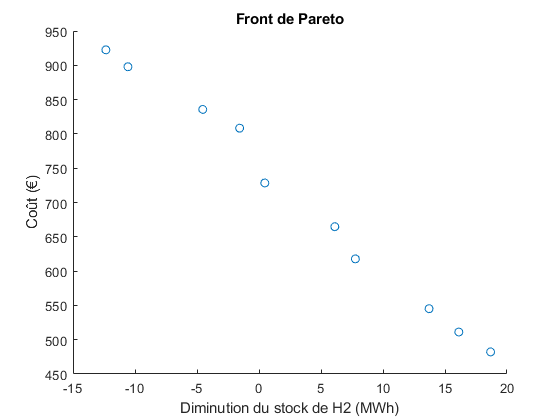

figure
scatter(fval_ps(:,1),fval_ps(:,2))
xlabel('Diminution du stock de H2 (MWh)')
ylabel('Coût (€)')
title('Front de Pareto')

On remarque que paretosearch a de meilleures valeurs que gamultiobj et ce peut importe la valeur de ParetoFraction (ici fixé à n_points/n_pop pour avoir le bon nombre de points)

### Test avec des epsilon-contraintes sur gs

pop = 200;
fobj_test =  @(P) (P(1,1:N) + D - Ppv - Peol - P(1,N+1:2*N))*Prix + Celec*sum(P(1,1:N)) + Cpac*sum(P(1,N+1:2*N));
x0 = zeros(1,2*N);
QH2_max_k = linspace(-15,20,n_points);
bk = b;
sol = zeros(2,n_points);
for k = 1:n_points  
    On = randi(2,1,N) - 1;
    Init = [On.*rand(1,N)*QH2_prod_max/relec/24 , (1 - On).*rand(1,N)*QH2_max_k(k)*rpac/24];
    bk(1) = QH2_max_k(k);
    probleme = createOptimProblem('fmincon','x0',x0,'objective',fobj_test,'lb',lb,'ub',ub,'Aineq',A,'bineq',bk);
    [x,fval,exitflag,output,solutions] = run(GlobalSearch,probleme);
    sol(2,k) = fval;
    sol(1,k) = sum(x(1,N+1:2*N))/rpac - sum(x(1,1:N))*relec;
end

GlobalSearch stopped because it analyzed all the trial points.

All 51 local solver runs converged with a positive local solver exit flag.

GlobalSearch stopped because it analyzed all the trial points.

All 44 local solver runs converged with a positive local solver exit flag.

GlobalSearch stopped because it analyzed all the trial points.

All 54 local solver runs converged with a positive local solver exit flag.

GlobalSearch stopped because it analyzed all the trial points.

All 72 local solver runs converged with a positive local solver exit flag.

GlobalSearch stopped because it analyzed all the trial points.

All 45 local solver runs converged with a positive local solver exit flag.

GlobalSearch stopped because it analyzed all the trial points.

All 48 local solver runs converged with a positive local solver exit flag.

GlobalSearch stopped because it analyzed all the trial points.

All 51 local solver runs converged with a positive local solver exit flag.

GlobalSearch stopped

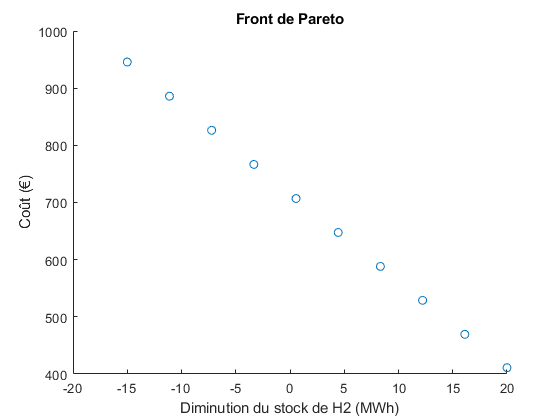

figure
scatter(sol(1,:),sol(2,:))
xlabel('Diminution du stock de H2 (MWh)')
ylabel('Coût (€)')
title('Front de Pareto')

On obtient des valeurs optimales (moyennant un temps de calcul plus long). On remarque que les valeurs obtenues sont plûto similaires à celles de Paretosearch.